## Machine Learning for Engineers: [ImbalancedData](https://www.apmonitor.com/pds/index.php/Main/ImbalancedData)

- Description: Identify imbalanced data and use undersampling or oversampling to improve the machine learning classification results

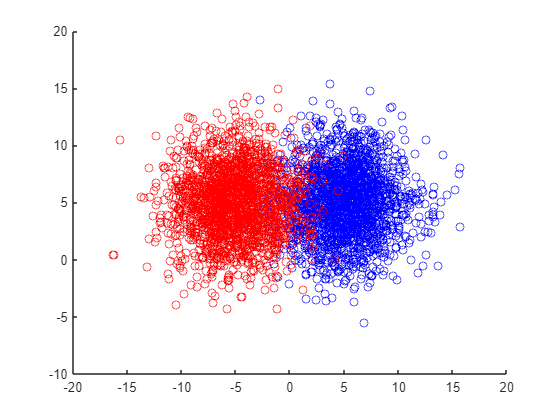

%%%TODO: This is incomplete. We are hung up on creating random data with 
%%% labels. Consult sponsors for advice how to proceed, as we can find no 
%%answers online


%create balanced data
numSamples = 2000;
stdDev = 3;

x1 = 5 + stdDev*randn(numSamples,1);
y1 = 5 + stdDev*randn(numSamples,1);
x2 = -5 + stdDev*randn(numSamples,1);
y2 = 5 + stdDev*randn(numSamples,1);

x = [x1;x2];
y = [y1;y2];

%Plot the data 
figure;
scatter(x1,y1,'blue');
hold on;
scatter(x2, y2, 'r');

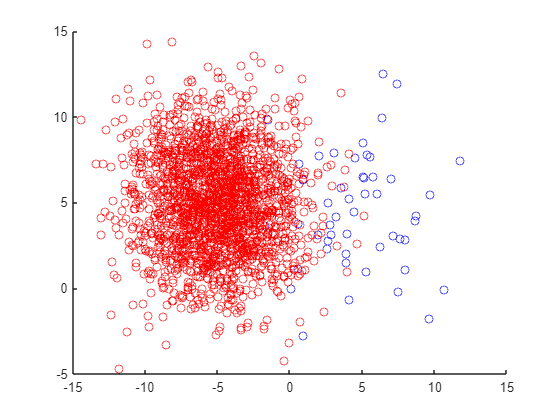


%%Undersample 

numSamples1 = 50;
numSamples2 = 2000;
stdDev = 3;

x1 = 5 + stdDev*randn(numSamples1,1);
y1 = 5 + stdDev*randn(numSamples1,1);
x2 = -5 + stdDev*randn(numSamples2,1);
y2 = 5 + stdDev*randn(numSamples2,1);

x = [x1;x2];
y = [y1;y2];
%Plot the data 
figure;
scatter(x1,y1,'blue');
hold on;
scatter(x2, y2, 'r');


max1 = max(max(x1),max(x2));
min1 = min(min(x1),min(x2));

max2 = max(max(y1),max(y2));
min2 = min(min(y1),min(y2));

x1grid = min1:0.1:max1

x1grid =   -14.3867  -14.2867  -14.1867  -14.0867  -13.9867  -13.8867  -13.7867  -13.6867  -13.5867  -13.4867  -13.3867  -13.2867  -13.1867  -13.0867  -12.9867  -12.8867  -12.7867  -12.6867  -12.5867  -12.4867  -12.3867  -12.2867  -12.1867  -12.0867  -11.9867  -11.8867  -11.7867  -11.6867  -11.5867  -11.4867  -11.3867  -11.2867  -11.1867  -11.0867  -10.9867  -10.8867  -10.7867  -10.6867  -10.5867  -10.4867  -10.3867  -10.2867  -10.1867  -10.0867   -9.9867   -9.8867   -9.7867   -9.6867   -9.5867   -9.4867


x2grid = min2:0.1:max2

x2grid =    -4.6508   -4.5508   -4.4508   -4.3508   -4.2508   -4.1508   -4.0508   -3.9508   -3.8508   -3.7508   -3.6508   -3.5508   -3.4508   -3.3508   -3.2508   -3.1508   -3.0508   -2.9508   -2.8508   -2.7508   -2.6508   -2.5508   -2.4508   -2.3508   -2.2508   -2.1508   -2.0508   -1.9508   -1.8508   -1.7508   -1.6508   -1.5508   -1.4508   -1.3508   -1.2508   -1.1508   -1.0508   -0.9508   -0.8508   -0.7508   -0.6508   -0.5508   -0.4508   -0.3508   -0.2508   -0.1508   -0.0508    0.0492    0.1492    0.2492



%%Create MeshGrid 
[xx,yy] = meshgrid(x1grid,x2grid)

xx =   -14.3867  -14.2867  -14.1867  -14.0867  -13.9867  -13.8867  -13.7867  -13.6867  -13.5867  -13.4867  -13.3867  -13.2867  -13.1867  -13.0867  -12.9867  -12.8867  -12.7867  -12.6867  -12.5867  -12.4867  -12.3867  -12.2867  -12.1867  -12.0867  -11.9867  -11.8867  -11.7867  -11.6867  -11.5867  -11.4867  -11.3867  -11.2867  -11.1867  -11.0867  -10.9867  -10.8867  -10.7867  -10.6867  -10.5867  -10.4867  -10.3867  -10.2867  -10.1867  -10.0867   -9.9867   -9.8867   -9.7867   -9.6867   -9.5867   -9.4867
  -14.3867  -14.2867  -14.1867  -14.0867  -13.9867  -13.8867  -13.7867  -13.6867  -13.5867  -13.4867  -13.3867  -13.2867  -13.1867  -13.0867  -12.9867  -12.8867  -12.7867  -12.6867  -12.5867  -12.4867  -12.3867  -12.2867  -12.1867  -12.0867  -11.9867  -11.8867  -11.7867  -11.6867  -11.5867  -11.4867  -11.3867  -11.2867  -11.1867  -11.0867  -10.9867  -10.8867  -10.7867  -10.6867  -10.5867  -10.4867  -10.3867  -10.2867  -10.1867  -10.0867   -9.9867   -9.8867   -9.7867   -9.6867   -9.5867   -

yy =    -4.6508   -4.6508   -4.6508   -4.6508   -4.6508   -4.6508   -4.6508   -4.6508   -4.6508   -4.6508   -4.6508   -4.6508   -4.6508   -4.6508   -4.6508   -4.6508   -4.6508   -4.6508   -4.6508   -4.6508   -4.6508   -4.6508   -4.6508   -4.6508   -4.6508   -4.6508   -4.6508   -4.6508   -4.6508   -4.6508   -4.6508   -4.6508   -4.6508   -4.6508   -4.6508   -4.6508   -4.6508   -4.6508   -4.6508   -4.6508   -4.6508   -4.6508   -4.6508   -4.6508   -4.6508   -4.6508   -4.6508   -4.6508   -4.6508   -4.6508
   -4.5508   -4.5508   -4.5508   -4.5508   -4.5508   -4.5508   -4.5508   -4.5508   -4.5508   -4.5508   -4.5508   -4.5508   -4.5508   -4.5508   -4.5508   -4.5508   -4.5508   -4.5508   -4.5508   -4.5508   -4.5508   -4.5508   -4.5508   -4.5508   -4.5508   -4.5508   -4.5508   -4.5508   -4.5508   -4.5508   -4.5508   -4.5508   -4.5508   -4.5508   -4.5508   -4.5508   -4.5508   -4.5508   -4.5508   -4.5508   -4.5508   -4.5508   -4.5508   -4.5508   -4.5508   -4.5508   -4.5508   -4.5508   -4.5508   -

r1 = xx(:)

r1 =   -14.3867
  -14.3867
  -14.3867
  -14.3867
  -14.3867
  -14.3867
  -14.3867
  -14.3867
  -14.3867
  -14.3867


r2 = yy(:);
grid = [r1 r2]

grid =   -14.3867   -4.6508
  -14.3867   -4.5508
  -14.3867   -4.4508
  -14.3867   -4.3508
  -14.3867   -4.2508
  -14.3867   -4.1508
  -14.3867   -4.0508
  -14.3867   -3.9508
  -14.3867   -3.8508
  -14.3867   -3.7508


## Fit to model

%%%%TODO::: Stuck here -> unsure of data processing in MATLAB with regards
%%%%to make_blob function 
features = rand(1000,2) 

features =     0.8147    0.6312
    0.9058    0.3551
    0.1270    0.9970
    0.9134    0.2242
    0.6324    0.6525
    0.0975    0.6050
    0.2785    0.3872
    0.5469    0.1422
    0.9575    0.0251
    0.9649    0.4211


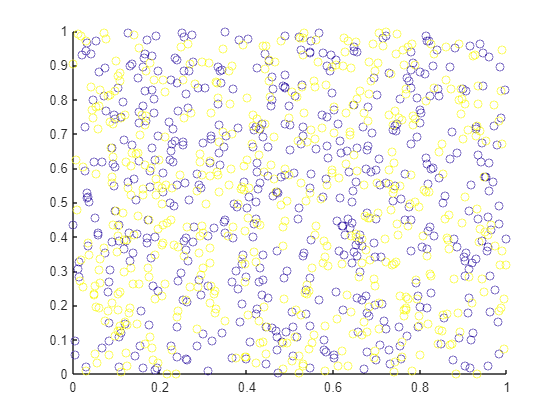

labels = [ones(500,1);ones(500,1)*2];
scatter(features(:,1),features(:,2),[],labels); 

label = population(randperm(2000))

Unrecognized function or variable 'population'.